# WINDSURFER/NORA3, hindcast 3km hourly 2D wave spectra

The present example illustrates the extraction of hourly 2D wave spectra from hindcast data produced by WINDSURFER/NORA3. The institution that provided the data is the Norwegian Meteorological Institute. The WAM wave model version cycle 4.7.0 was used to generate the 2D wave spectra. The direction convention is here following the so-called Oceanographic convention. That means that a direction of 0 degrees corresponds to waves propagating towards the North. So it is an offset of 180 deg with the wind direction convention.

## Initialisation

The wave spectra are extracted for 26 directions; the first and last one are overlapping. The frequency vector length is 30 with frequencies up to ca. 0.5 Hz. In the present example, the 2D spectra are extracted every 12 hours between the 2017-12-08 and 2017-12-10 in one location. The current version of the function does not allow the extraction of multiple locations at the same time.


clearvars;close all;clc;
targetDate = datetime(2017,12,08,14,0,0):duration(12,0,0):datetime(2017,12,10,14,0,0);
targetLat = 54; % target latitude (between 52 and 74)
targetLon = 7;  % target longitude (between -11 and 42)
N = numel(targetDate);
Nfreq = 30; % 30 frequency steps
Ntheta = 26; % number of directions

## Main loop


time = NaT(1,N);
S = nan(Ntheta,Nfreq,N);
for ii=1:N
    tic
    targetYear = num2str(year(targetDate(ii)));
    targetMonth = num2str(month(targetDate(ii)));
    targetDay = num2str(day(targetDate(ii)));
    targetHour = num2str(hour(targetDate(ii)));
    
    if numel(targetHour)==1, targetHour = ['0',targetHour];end
    if numel(targetDay)==1, targetDay = ['0',targetDay];end
    if numel(targetMonth)==1, targetMonth = ['0',targetMonth];end
    
    [data] = get2DSS(targetLat,targetLon,targetYear,targetMonth,targetDay,targetHour);
    toc
    time(ii)= data.time;
    S(:,:,ii) = data.S;
    theta = data.theta; % direction
    f = data.f; % frequency
end

Number of locations used for interpolation: 10 


Elapsed time is 2.777612 seconds.


Number of locations used for interpolation: 10 


Elapsed time is 2.228662 seconds.


Number of locations used for interpolation: 10 


Elapsed time is 1.775674 seconds.


Number of locations used for interpolation: 10 


Elapsed time is 2.026626 seconds.


Number of locations used for interpolation: 10 


Elapsed time is 1.692971 seconds.


## Plot the 2D wave spectrum in a polar coordinate system

The function polarpcolor is used. it is available [here](https://se.mathworks.com/matlabcentral/fileexchange/49040-pcolor-in-polar-coordinates).

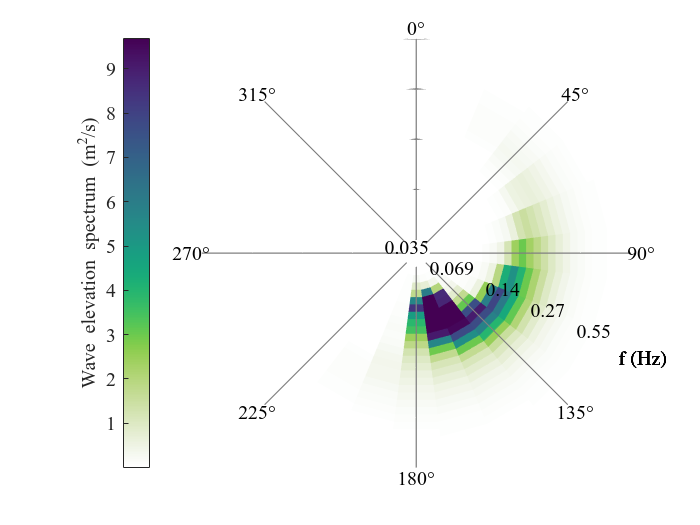

if ~exist('polarpcolor.m','file')
    warning('No plot produced. You need the function polarpcolor for that. It is available here: https://se.mathworks.com/matlabcentral/fileexchange/49040-pcolor-in-polar-coordinates');
else
    indTime = min(2,N);
    clf;close all;
    figure
    [h,c]=polarPcolor(f',theta',S(:,:,indTime)','Nspokes',9,'labelR','f (Hz)','Rscale','log');
    if exist('viridis_white.m','file')
        colormap(flipud(colormap('viridis_white')));
    end
    set(gcf,'color','w')
    ylabel(c,'Wave elevation spectrum (m^2/s)')
    set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')
end

## Plot the wave spectra as a function of the frequency in a log axis

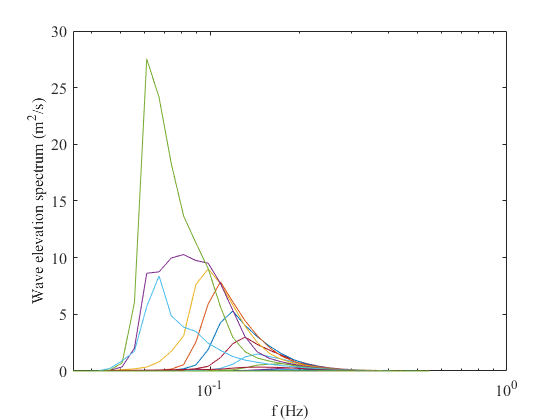

figure
semilogx(f,S(:,:,indTime))
xlabel('f (Hz)')
ylabel('Wave elevation spectrum (m^2/s)')
set(gcf,'color','w')
set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')